% Week 12 example code for training a simple SVM classifier on the
% CUB_200_2011_Subset20classes dataset using SURF features.
%
% Author: Roland Goecke
% Date created: 26/04/2022
% Date last updated: 10/04/2023

close all;
clear variables;
clc;

## Read the training, validation and test partitions from the relevant

folder = "..\CUB_200_2011_Subset20classes\";
trainingImageNames = readtable(fullfile(folder, "train.txt"), ...
    'ReadVariableNames', false);
trainingImageNames.Properties.VariableNames = {'index', 'imageName'};

validationImageNames = readtable(folder + "validate.txt", ...
    'ReadVariableNames', false);
validationImageNames.Properties.VariableNames = {'index', 'imageName'};

testImageNames = readtable(folder + "test.txt", ...
    'ReadVariableNames', false);
testImageNames.Properties.VariableNames = {'index', 'imageName'};

## Read class info from the relevant text files

classNames = readtable(folder + "classes.txt", ...
    'ReadVariableNames', false);
classNames.Properties.VariableNames = {'index', 'className'};

imageClassLabels = readtable(folder + "image_class_labels.txt", ...
    'ReadVariableNames', false);
imageClassLabels.Properties.VariableNames = {'index', 'classLabel'};

## Create lists of image names for training, validation and test subsets.

trainingImageList = strings(height(trainingImageNames), 1);
for iI = 1:height(trainingImageNames)
    trainingImageList(iI) = string(fullfile(folder, "images/", ...
        string(cell2mat(trainingImageNames.imageName(iI)))));
end

validationImageList = strings(height(validationImageNames), 1);
for iI = 1:height(validationImageNames)
    validationImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(validationImageNames.imageName(iI))));
end

testImageList = strings(height(testImageNames), 1);
for iI = 1:height(testImageNames)
    testImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(testImageNames.imageName(iI))));
end

## Create image datastores for training, validation and test subsets

trainingImageDS = imageDatastore(trainingImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
trainingImageDS.ReadFcn = @readImagesIntoDatastore;
disp('Training set class distribution:');

Training set class distribution:


countEachLabel(trainingImageDS)

ans = 20×2 table
    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  



validationImageDS = imageDatastore(validationImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
validationImageDS.ReadFcn = @readImagesIntoDatastore;
disp('Validation set class distribution:');

Validation set class distribution:


countEachLabel(validationImageDS)

ans = 20×2 table
    Label    Count
    _____    _____

     001       6  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  



testImageDS = imageDatastore(testImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
testImageDS.ReadFcn = @readImagesIntoDatastore;
disp('Test set class distribution:');

Test set class distribution:


countEachLabel(testImageDS)

ans = 20×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  


## The images all have different spatial resolutions (width x height), so

targetSize = [100, 100];
trainingImageDS_Resized = transform(trainingImageDS, @(x) imresize(x,targetSize));
validationImageDS_Resized = transform(validationImageDS, @(x) imresize(x,targetSize));
testImageDS_Resized = transform(testImageDS, @(x) imresize(x,targetSize));

% Combine transformed datastores and labels
labelsTraining = arrayDatastore(trainingImageDS.Labels);
cdsTraining = combine(trainingImageDS_Resized, labelsTraining);
labelsValidation = arrayDatastore(validationImageDS.Labels);
cdsValidation = combine(validationImageDS_Resized, labelsValidation);
labelsTest = arrayDatastore(testImageDS.Labels);
cdsTest = combine(testImageDS_Resized, labelsTest);

## Display a sample image from the datastore and HOG features

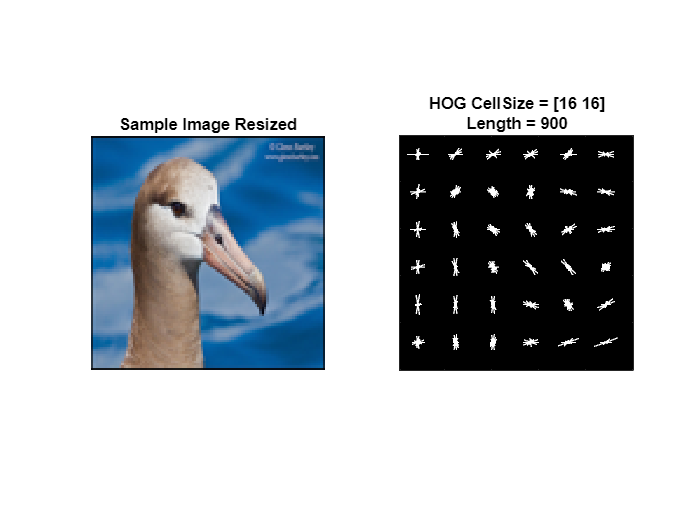

figure(1);
img = cdsTraining.read{1};
[hog_16x16, vis16x16] = extractHOGFeatures(img,'CellSize',[16 16]);
subplot(1, 2, 1);
imshow(img);
title('Sample Image Resized');
subplot(1, 2, 2);
plot(vis16x16);
title({'HOG CellSize = [16 16]'; ['Length = ' num2str(length(hog_16x16))]});

## Extract HOG features

cellSize = [16 16];     % Set cell size to 16x16
hogFeatureSize = length(hog_16x16);

% Start by extracting HOG features from the training set. These features
% will be used to train the classifier.
% Loop over the trainingSet and extract HOG features from each image.
numImagesTrain = numel(trainingImageDS_Resized.UnderlyingDatastores{1, 1}.Files);
trainingFeatures = zeros(numImagesTrain, hogFeatureSize, 'single');
reset(cdsTraining);     % Make sure we start with the first image
for i = 1:numImagesTrain
    imgFromDS = read(cdsTraining);    % Get item from datastore. Note, this returns a cell array.
    imgGray = im2gray(imgFromDS{1});      % Ensure images are grayscale
    
    trainingFeatures(i, :) = extractHOGFeatures(imgGray, 'CellSize', cellSize);
end

% Now extract HOG features from the test set as well.
numImagesTest = numel(testImageDS_Resized.UnderlyingDatastores{1, 1}.Files);
testFeatures = zeros(numImagesTest, hogFeatureSize, 'single');
reset(cdsTest);     % Make sure we start with the first image
for i = 1:numImagesTest
    imgFromDS = read(cdsTest);    % Get item from datastore
    imgGray = im2gray(imgFromDS{1});  % Ensure images are grayscale
    
    testFeatures(i, :) = extractHOGFeatures(imgGray, 'CellSize', cellSize);
end

## Check if we have a GPU available and clear any old data from it

if (gpuDeviceCount() > 0)
    disp('Found GPU:');
    disp(gpuDeviceTable);
    device = gpuDevice(1);
    reset(device);  % Clear previous values that might still be on the GPU
end

Found GPU:


    Index                     Name                      ComputeCapability    DeviceAvailable    DeviceSelected
    _____    _______________________________________    _________________    _______________    ______________

      1      "NVIDIA GeForce RTX 3050 Ti Laptop GPU"          "8.6"               true              true      



## Train a multi-class SVM

Copying objective function to workers...
Done copying objective function to workers.
|================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |
|================================================================================================|
|    1 |       8 | Best   |     0.90691 |      9.3453 |     0.90691 |     0.90691 |       52.395 |
|    2 |       2 | Accept |     0.84084 |      9.5869 |     0.83483 |     0.83658 |    0.0043757 |
|    3 |       2 | Accept |     0.85886 |      9.5266 |     0.83483 |     0.83658 |   1.4117e-05 |
|    4 |       2 | Best   |     0.83483 |      9.4453 |     0.83483 |     0.83658 |   1.6264e-08 |
|    5 |       2 | Accept |     0.87237 |      9.4127 |     0.83483 |     0.83658 |      0.33605 |
|    6 |       2 | Accep

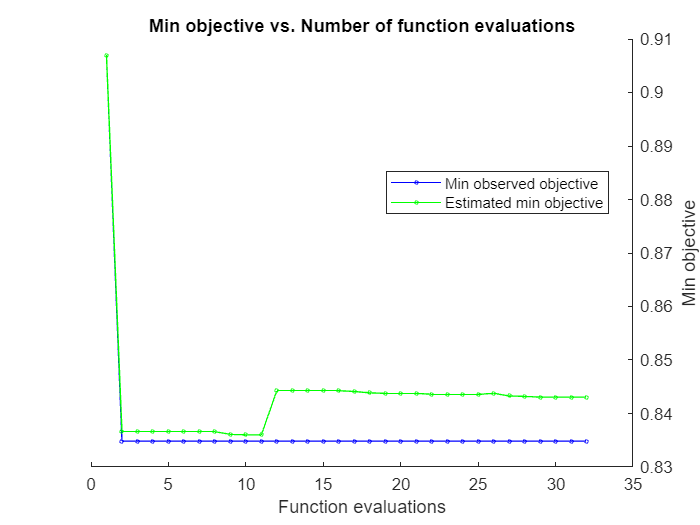

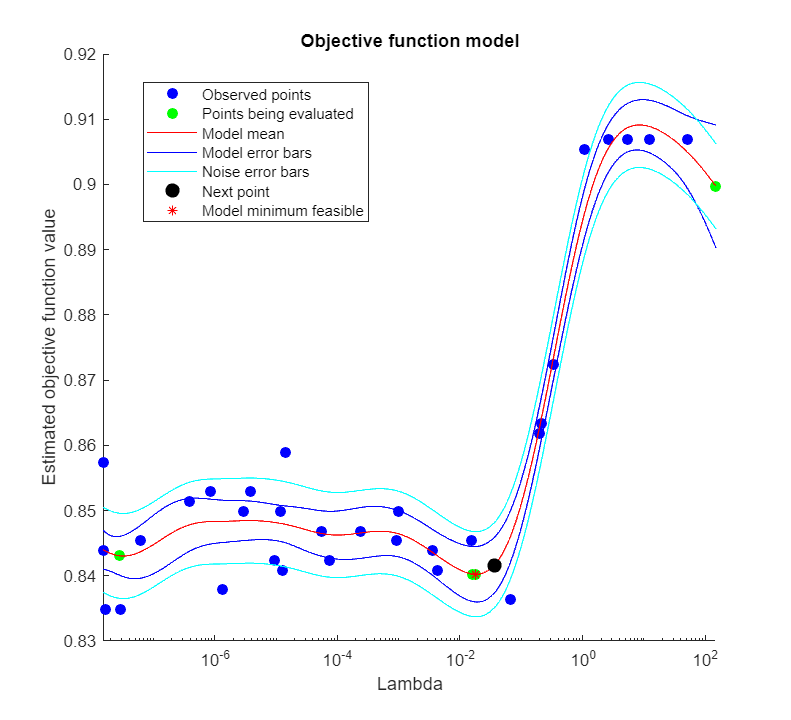


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 32
Total elapsed time: 41.5124 seconds
Total objective function evaluation time: 295.502

Best observed feasible point:
      Lambda  
    __________

    1.6264e-08

Observed objective function value = 0.83483
Estimated objective function value = 0.84383
Function evaluation time = 9.4453

Best estimated feasible point (according to models):
      Lambda  
    __________

    2.8779e-08

Estimated objective function value = 0.84305
Estimated function evaluation time = 9.2289



t = templateLinear('Solver', 'dual');
options = struct('UseParallel', true);

% fitcecoc uses multiple SVM learners and a 'One-vs-One' encoding scheme.
Classifier = fitcecoc(trainingFeatures, trainingImageDS.Labels, 'Learners', t, ...
    'OptimizeHyperparameters', {'Lambda'}, ...
    'HyperparameterOptimizationOptions', options);

## Test the accuracy on the test partition

YPred = predict(Classifier, testFeatures);
YTest = testImageDS.Labels;

% Calculate overall accuracy
accuracy = sum(YPred == YTest)/numel(YTest) % Output on command line

accuracy = 0.1847

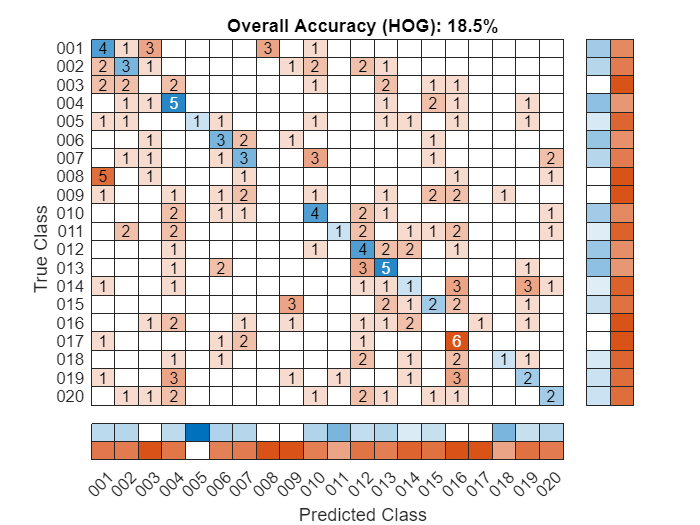


% Show confusion matrix in figure
[m, order] = confusionmat(YTest, YPred);
figure(2);
cm = confusionchart(m, order, ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');
title("Overall Accuracy (HOG): "+ string(round(accuracy*100, 1)) +"%");